%8.4（前面两问在lab7中已经做完了）
clc, clear, close all;

wp = 1.8;
ws = 2.2;
delta_p = 0.05;    % 通带允许最大波纹
delta_s = 0.005;   % 阻带允许最大波纹

[n, fo, ao, w] = firpmord([wp ws], [1 0], [delta_p delta_s], 2*pi);
b = firpm(n, fo, ao, w);
[H, w_freq] = freqz(b, 1, 1024, 2*pi); 

pass_idx = find(w_freq <= wp); % 0 到 1.8 的区域
stop_idx = find(w_freq >= ws); % 2.2 到 pi 的区域
measured_pass_ripple = max(abs(abs(H(pass_idx)) - 1));
measured_stop_ripple = max(abs(H(stop_idx)));
measured_stop_ripple_db = 20*log10(measured_stop_ripple);

fprintf('==============================================\n');

fprintf('       Parks-McClellan Filter Design Check    \n');

       Parks-McClellan Filter Design Check    


fprintf('==============================================\n');

fprintf('Filter Order (n)      : %d\n', n);

Filter Order (n)      : 25


fprintf('Filter Length (n+1)   : %d\n', n+1);

Filter Length (n+1)   : 26


fprintf('----------------------------------------------\n');

----------------------------------------------


fprintf('Passband Ripple Spec  : %.4f\n', delta_p);

Passband Ripple Spec  : 0.0500


fprintf('Measured Pass Ripple  : %.5f  [%s]\n', ...
    measured_pass_ripple, check_spec(measured_pass_ripple, delta_p));

Measured Pass Ripple  : 0.05470  [FAIL]


fprintf('----------------------------------------------\n');

----------------------------------------------


fprintf('Stopband Ripple Spec  : %.4f (approx -46 dB)\n', delta_s);

Stopband Ripple Spec  : 0.0050 (approx -46 dB)


fprintf('Measured Stop Ripple  : %.5f  [%s]\n', ...
    measured_stop_ripple, check_spec(measured_stop_ripple, delta_s));

Measured Stop Ripple  : 0.00547  [FAIL]


fprintf('Measured Stop dB      : %.2f dB\n', measured_stop_ripple_db);

Measured Stop dB      : -45.24 dB


fprintf('==============================================\n');


if measured_pass_ripple <= delta_p && measured_stop_ripple <= delta_s
    fprintf('结论: firpmord 估算准确 (Accurate)。\n');
    fprintf('当前阶数 n=%d 已满足所有设计要求。\n', n);
else
    fprintf('结论: firpmord 估算偏低 (Underestimated)。\n');
    fprintf('当前阶数 n=%d 未能完全满足要求，请尝试 n = %d。\n', n, n+1);
end

结论: firpmord 估算偏低 (Underestimated)。


当前阶数 n=25 未能完全满足要求，请尝试 n = 26。


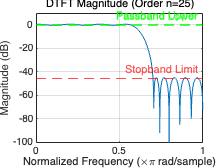


figure;
plot(w_freq/pi, 20*log10(abs(H)));
hold on;
yline(20*log10(delta_s), 'r--', 'Stopband Limit');
yline(20*log10(1+delta_p), 'g--', 'Passband Upper');
yline(20*log10(1-delta_p), 'g--', 'Passband Lower');
hold off;

xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title(['DTFT Magnitude (Order n=' num2str(n) ')']);
grid on;
xlim([0 1]);
ylim([-100 10]);

这里的滤波器长度是26，Kaiser约为51，可发现大致是Kaiser的一半左右。

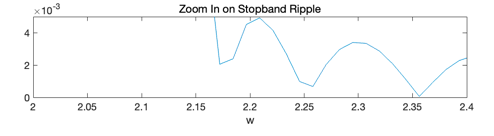

频率响应的波形区别如下：

- **Parks-McClellan (PM) 滤波器：**是**等波纹 (Equiripple)** 的。它的所有波峰（旁瓣）高度都是一样的，都顶着设计限制线。

- **Kaiser 窗滤波器：** 是 **衰减 (Decaying)** 的。它的旁瓣（Sidelobes）在截止频率附近最高，然后随着频率变大，波峰越来越低

load nspeech2.mat;
filtered_signal = filter(b, 1, nspeech2);
dtft_points = 1024;
[H,w] = DTFT(nspeech2(20001:20400),dtft_points);
[Filtered_H, Filtered_w] = DTFT(filtered_signal(20001:20400), dtft_points);
figure;
subplot(211),plot(w, 20*log10(abs(H))),title('Unfiltered Signal DTFT Magnitude');
subplot(212),plot(Filtered_w, 20*log10(abs(Filtered_H))),title('Filtered Signal DTFT Magnitude');
sound(nspeech2, 8000);
pause(length(nspeech2) / 8000);
sound(filtered_signal, 8000);

Audio quality明显上升，和Kaiser滤波器相比，几乎听不出区别TuT

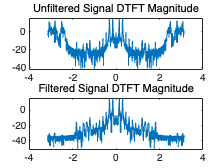

function s = check_spec(measured, limit)

    if measured <= limit
        s = 'PASS';
    else
        s = 'FAIL';
    end
end